# SIGNALS AND SYSTEMS PROJECT

# GROUP 2

# M.A.YAZDANI 400102255

## Electroencephalography (EEG)

- Electrode naming in 10-20 EEG system

One internationally recognized electrode placement method is the 10-20 system. This method was developed to maintain standardized testing methods ensuring that a subject’s study outcomes (clinical or research) could be compiled, reproduced, and effectively analyzed and compared using scientific methods. It is called 10-20 because the distance between adjacent electrodes is 10% or 20% of the skull’s total front–back or right–left distance.

                                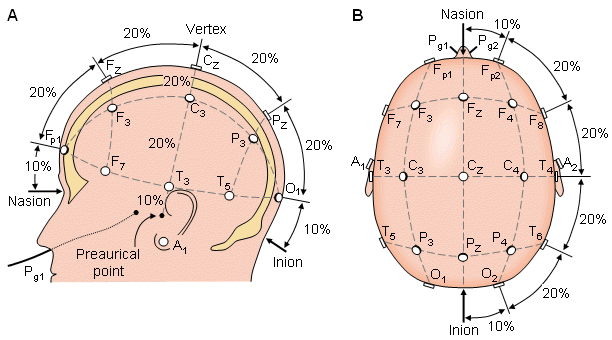

Each electrode placement site has a letter to identify the lobe, or area of the brain it is reading from: pre-frontal (Fp), frontal (F), temporal (T), parietal (P), occipital (O), and central (C). Note that there is no "central lobe"; due to their placement, and depending on the individual, the "C" electrodes can exhibit/represent EEG activity more typical of frontal, temporal, and some parietal-occipital activity, and are always utilized in polysomnography sleep studies for the purpose of determining stages of sleep.

There are also (Z) sites: A "Z" (zero) refers to an electrode placed on the midline sagittal plane of the skull, (FpZ, Fz, Cz, Oz) and is present mostly for reference/measurement points. These electrodes will not necessarily reflect or amplify lateral hemispheric cortical activity as they are placed over the corpus callosum, and do not represent either hemisphere adequately. "Z" electrodes are often utilized as 'grounds' or 'references,' especially in polysomnography sleep studies, and diagnostic/clinical EEG montages meant to represent/diagnose epileptiform seizure activity, or possible clinical brain death. Note that the required number of EEG electrodes, and their careful, measured placement, increases with each clinical requirement and modality.

Even-numbered electrodes (2,4,6,8) refer to electrode placement on the right side of the head, whereas odd numbers (1,3,5,7) refer to those on the left; this applies to both EEG and EOG (electrooculogram measurements of eyes) electrodes, as well as ECG (electrocardiography measurements of the heart) electrode placement. Chin, or EMG (electromyogram) electrodes are more commonly just referred to with "right," "left," and "reference," or "common," as there are usually only three placed, and they can be differentially referenced from the EEG and EOG reference sites.

The "A" (sometimes referred to as "M" for mastoid process) refers to the prominent bone process usually found just behind the outer ear (less prominent in children and some adults). In basic polysomnography, F3, F4, Fz, Cz, C3, C4, O1, O2, A1, A2 (M1, M2), are used. Cz and Fz are 'ground' or 'common' reference points for all EEG and EOG electrodes, and A1-A2 are used for contralateral referencing of all EEG electrodes. This EEG montage may be extended to utilize T3-T4, P3-P4, as well as others, if an extended or "seizure montage" is called for.

- What does each frequency band represent?

Delta:

Delta waves is the frequency range up to 4 Hz. It tends to be the highest in amplitude and the slowest waves. It is seen normally in adults in slow-wave sleep. It is also seen normally in babies. It may occur focally with subcortical lesions and in general distribution with diffuse lesions, metabolic encephalopathy hydrocephalus or deep midline lesions. It is usually most prominent frontally in adults (e.g. FIRDA – frontal intermittent rhythmic delta) and posteriorly in children (e.g. OIRDA – occipital intermittent rhythmic delta).

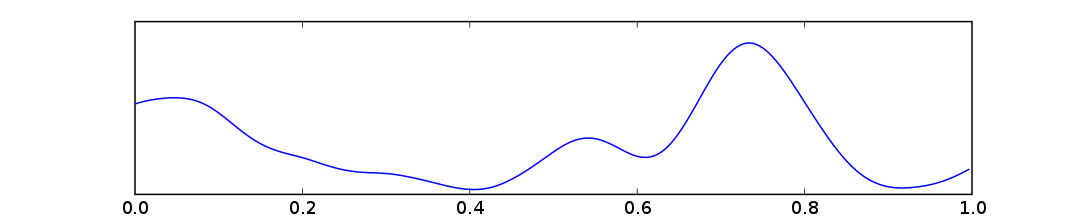

Theta:

Theta is the frequency range from 4 Hz to 7 Hz. Theta is seen normally in young children. It may be seen in drowsiness or arousal in older children and adults; it can also be seen in meditation.Excess theta for age represents abnormal activity. It can be seen as a focal disturbance in focal subcortical lesions; it can be seen in generalized distribution in diffuse disorder or metabolic encephalopathy or deep midline disorders or some instances of hydrocephalus. On the contrary this range has been associated with reports of relaxed, meditative, and creative states.

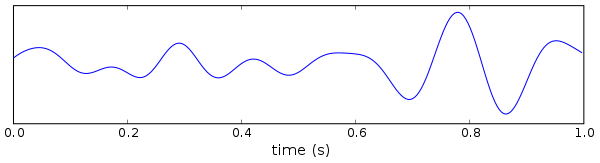

Alpha:

Alpha is the frequency range from 8 Hz to 12 Hz.Hans Berger named the first rhythmic EEG activity he observed the "alpha wave". This was the "posterior basic rhythm" (also called the "posterior dominant rhythm" or the "posterior alpha rhythm"), seen in the posterior regions of the head on both sides, higher in amplitude on the dominant side. It emerges with closing of the eyes and with relaxation, and attenuates with eye opening or mental exertion. The posterior basic rhythm is actually slower than 8 Hz in young children (therefore technically in the theta range). 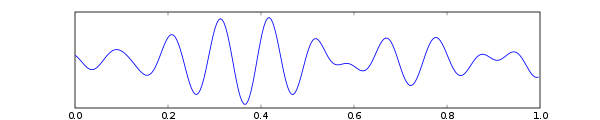

Beta:

Beta is the frequency range from 13 Hz to about 30 Hz. It is seen usually on both sides in symmetrical distribution and is most evident frontally. Beta activity is closely linked to motor behavior and is generally attenuated during active movements.Low-amplitude beta with multiple and varying frequencies is often associated with active, busy or anxious thinking and active concentration. Rhythmic beta with a dominant set of frequencies is associated with various pathologies, such as Dup15q syndrome, and drug effects, especially benzodiazepines. It may be absent or reduced in areas of cortical damage. It is the dominant rhythm in patients who are alert or anxious or who have their eyes open.

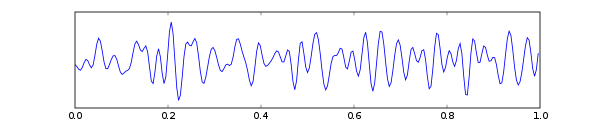

Gamma:

Gamma is the frequency range approximately 30–100 Hz. Gamma rhythms are thought to represent binding of different populations of neurons together into a network for the purpose of carrying out a certain cognitive or motor function.

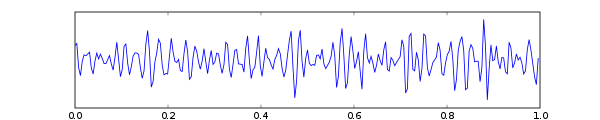

- Proper sampling frequencies for EEG signals

Minimum sampling frequency for any signal should be at least twice the frequency of the highest frequency component in your signal as it is stated in the Nyquist sampling theorem. 

Usually, EEG is filtered with a low pass filter with a cutoff frequency of  50Hz. So in theory, after filtration, all the components of the signal should have frequencies that are lower than 50Hz. So the minimum sample rate should be twice the 50Hz so it should be at least 100Hz.

Please note that that is the theoretical minimum that you need to satisfy. In order to have a more practical solution and nice-looking signal, usually, people sample EEG signal with few hundreds of Hz. Typically around 200Hz.

## EEG Signal  Processing

### pre-process 1

#### step 1:

clear;
load 'C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Preprocess\subject1'
Subject01 = transpose(table2array(subject1));
Subject01 = Subject01(1:19,:);
save Subject01.mat Subject01
figure
     EEG.etc.eeglabvers = '2023.0'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = pop_importdata('dataformat','matlab','nbchan',0,'data','C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\Dataset\\Dataset\\Preprocess\\Subject01.mat','setname','imported01','srate',200,'pnts',0,'xmin',0);

pop_editset(): raw data file 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\Dataset\\Dataset\\Preprocess\\Subject01.mat' found
eeg_checkset warning: number of columns in data (19) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (307634) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


     pop_eegplot( EEG, 1, 1, 1)

You are using a new version of eegplot - if you encounter problems
type "edit eegplot.m" and change FORCE_EEGPLOT_LEGACY to true


ans = 'pop_eegplot( EEG, 1, 1, 1);'

     EEG=pop_chanedit(EEG, []);

     EEG = pop_editset(EEG, 'chanlocs', 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\sample_locs\\Standard-10-20-Cap19.locs');

pop_editset(): channel locations file 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\sample_locs\\Standard-10-20-Cap19.locs' found
readlocs(): 'loc' format assumed from file extension


     EEG = pop_reref( EEG, []);

Re-referencing data


pop_eegfiltnew() - performing 1321 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): [0.5 40.5] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.25 40.75] Hz


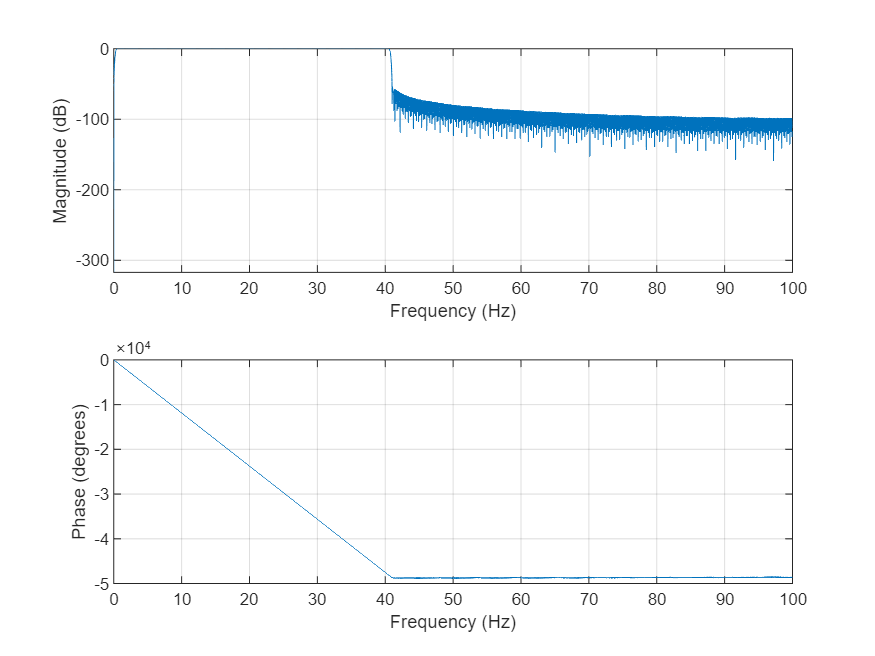

pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


     EEG.setname='imported01_reref';
     EEG = pop_eegfiltnew(EEG, 'locutoff',0.5,'hicutoff',40.5,'plotfreqz',5);

     EEG.setname='imported01_reref_fltr';

#### step 2:

 EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [19,307634] = 19 channels, 307634 frames/nFinding 19 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 852 frames per ICA weight ((361)^2 = 307634 weights, Initial learning rate will be 0.001, block size 64.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -22220.1 to 33995.9
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
Lowering learning rate to 0.0009 and starting again.
Lowering learning rate to 0.00081 and starting again.
Lowering learning rate to 0.000729 and

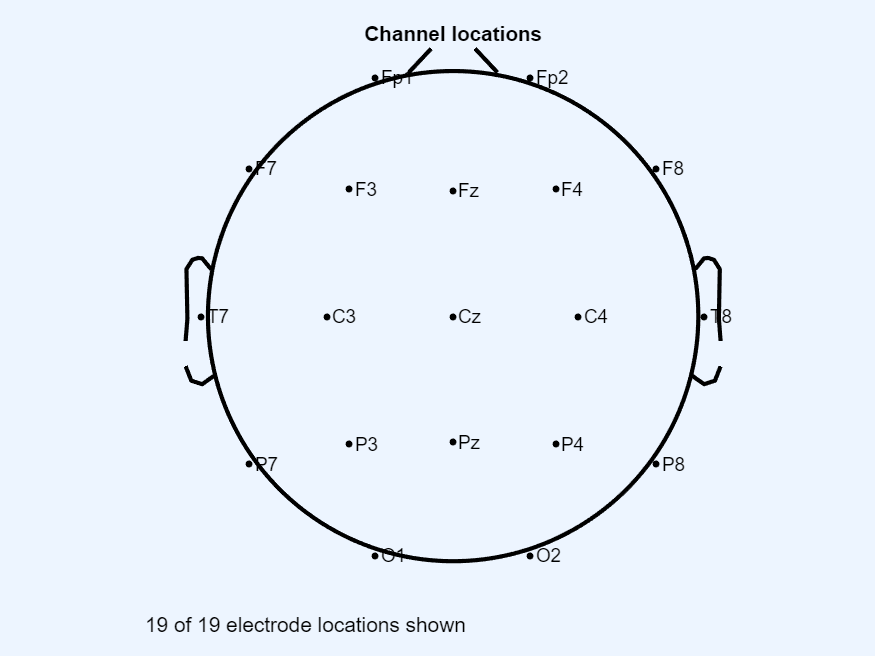

     figure; topoplot([],EEG.chanlocs, 'style', 'blank',  'electrodes', 'labelpoint', 'chaninfo', EEG.chaninfo);

     EEG = pop_iclabel(EEG, 'default');

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


     EEG = pop_subcomp( EEG, [1   2   3   4   5   7  18], 0);

Computing projection and removing 7 components ....


     EEG.setname='imported01_reref_fltr_ICA_Purebrain';
     EEG = eeg_checkset( EEG );
%      pop_eegplot( EEG, 1, 1, 1);

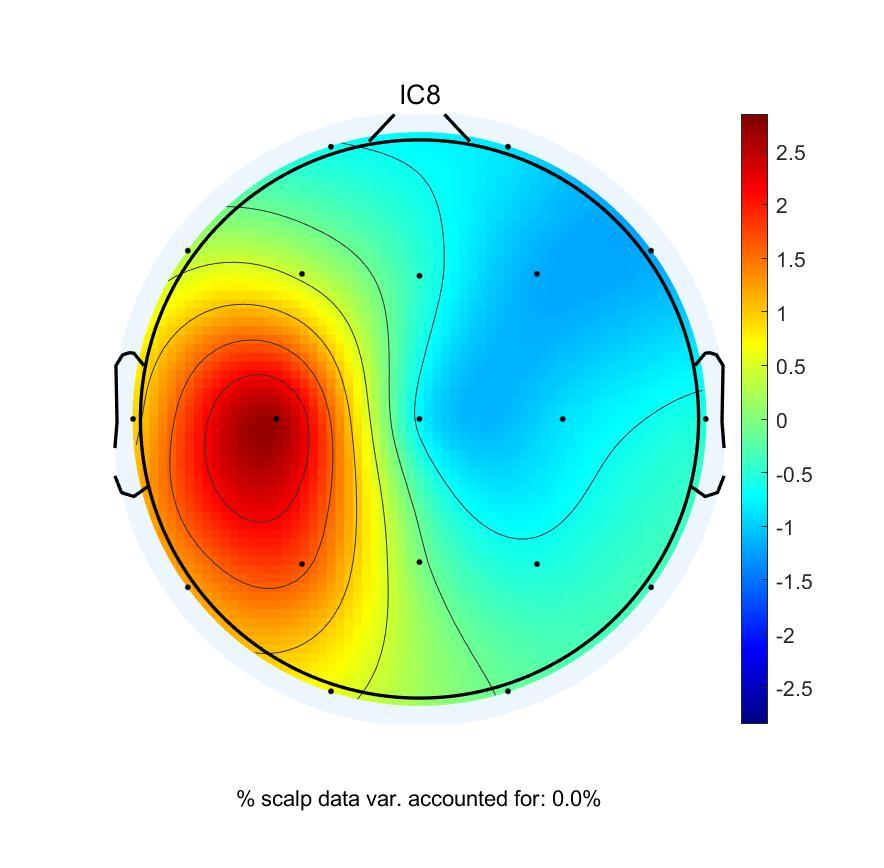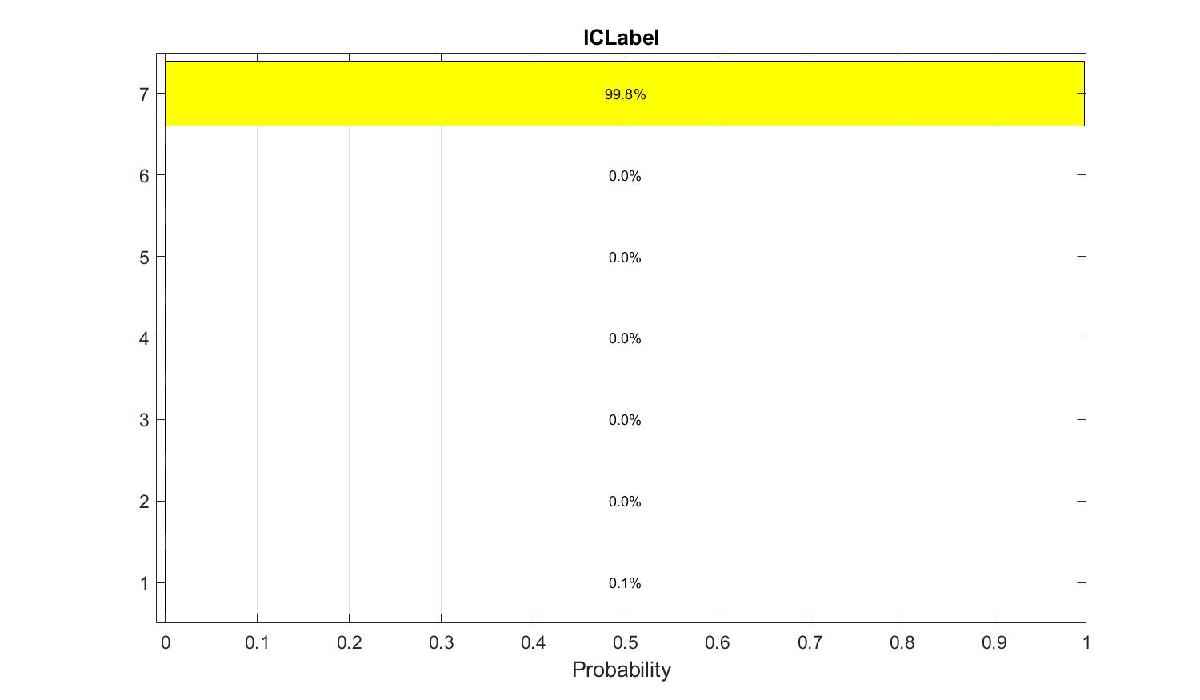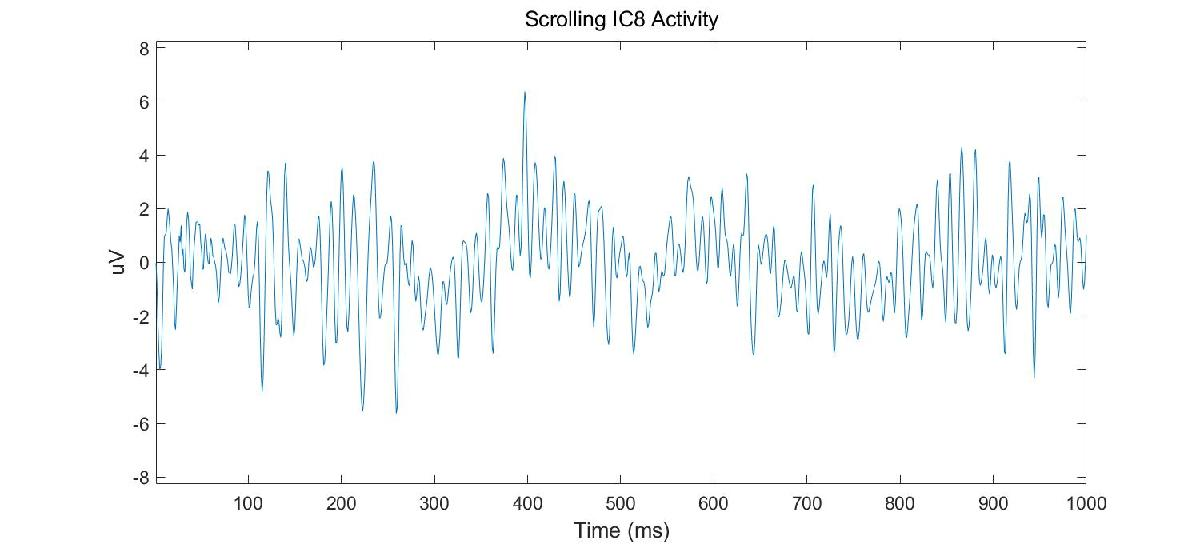

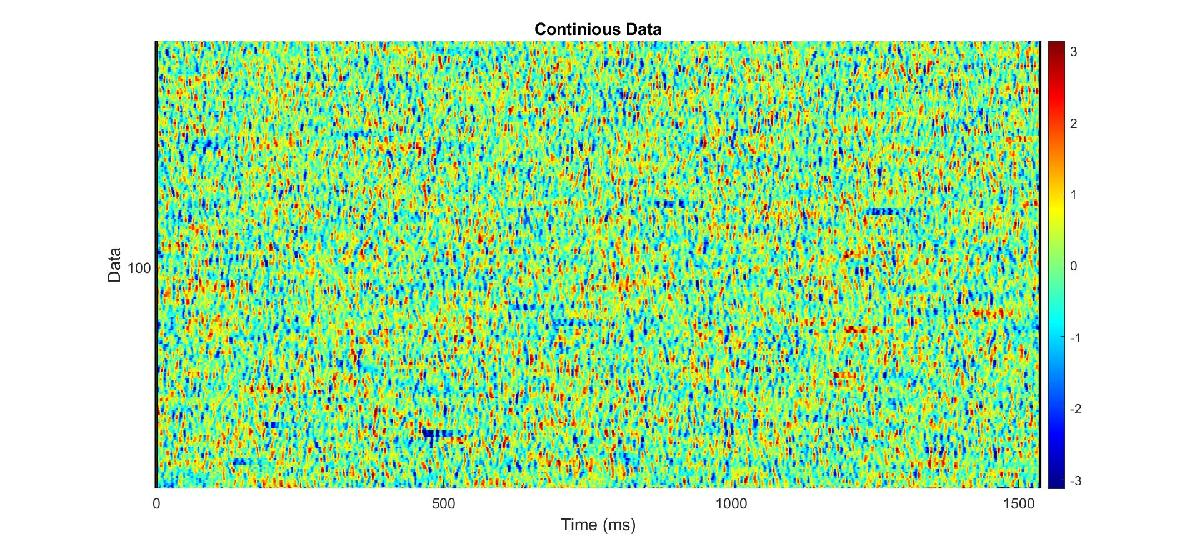     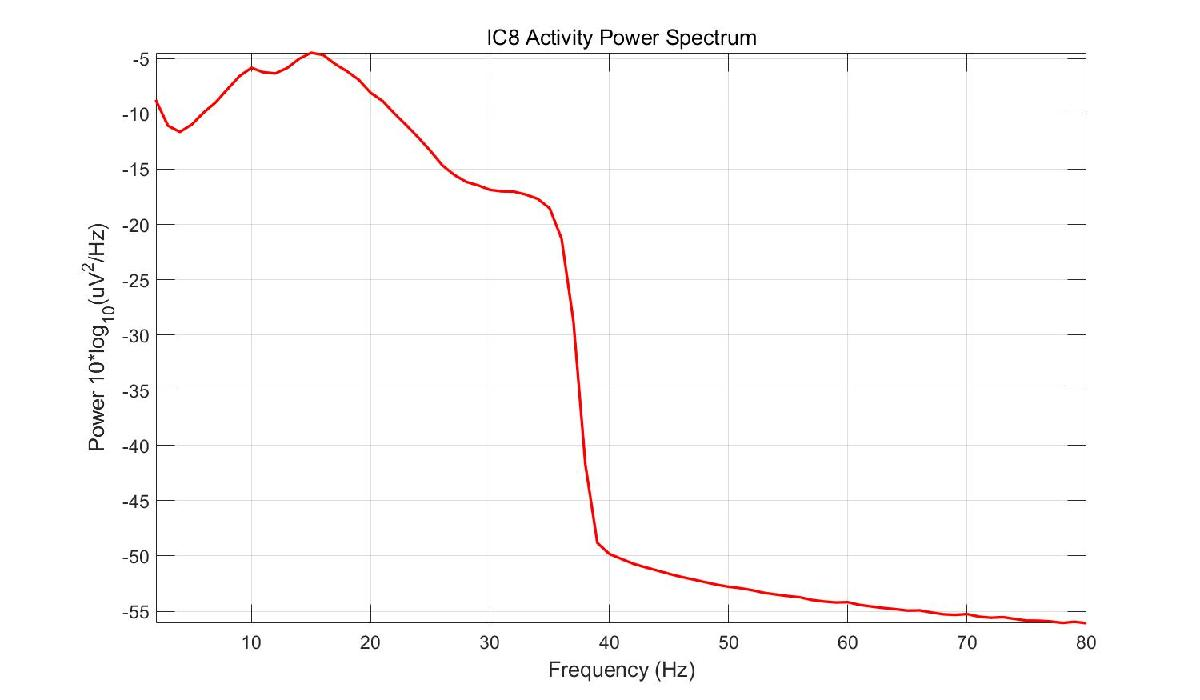

#### step 3:

a = EEG.data(1,1:240000);
b = reshape(a,[1 2000 120]);
for i=2:1:19
  a = EEG.data(i,1:240000);
  b = cat(1,b,reshape(a,[1 2000 120]));
end
b = b(:,1401:2000,:);
save Subject01_trials.mat b

#### step 4&5:

EEG.etc.eeglabvers = '2023.0'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = pop_importdata('dataformat','matlab','nbchan',0,'data','C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\Subject01_trials.mat','srate',200,'pnts',0,'xmin',0);

pop_editset(): raw data file 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\Subject01_trials.mat' found
eeg_checkset warning: number of columns in data (19) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (120) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (600) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


     EEG.setname='imported0101';
%      denoising excecution
     EEG.setname='imported0101_selected';
     EEG = eeg_checkset( EEG );
     EEG=pop_chanedit(EEG, []);

     EEG = pop_select( EEG, 'channel',{'Fp1','Fz','Cz','Pz'});

Removing 15 channel(s)...


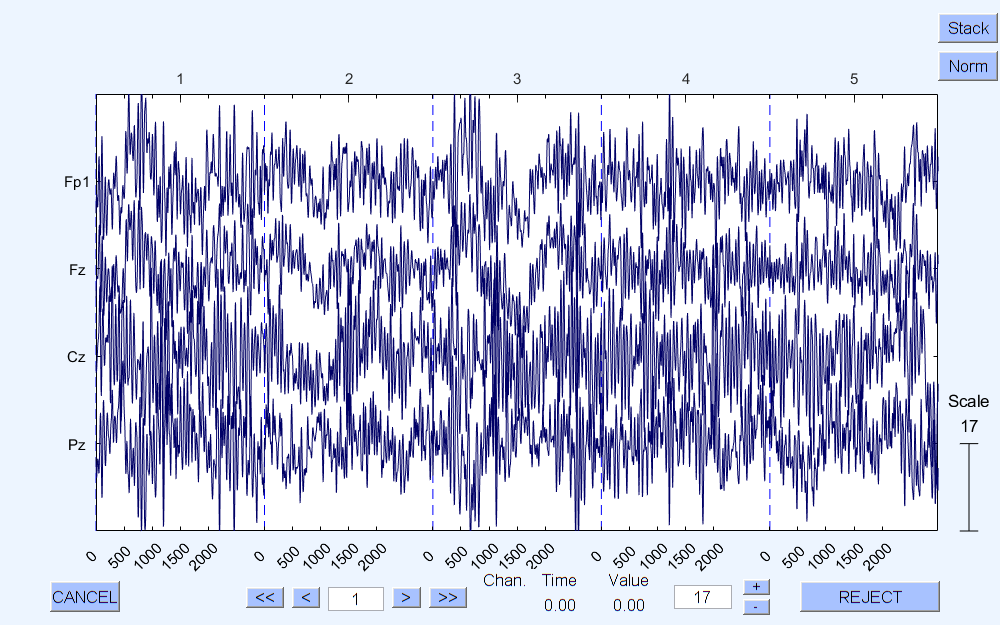

     EEG.setname='imported0101_selected_subbed';     
     EEG = eeg_checkset( EEG );
     pop_eegplot( EEG, 1, 1, 1);

### pre-process 2

#### all steps

     clear;
load 'C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Preprocess\subject2'
Subject02 = transpose(table2array(subject2));
Subject02 = Subject02(1:19,:);
save Subject02.mat Subject02 
EEG.etc.eeglabvers = '2023.0'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = pop_importdata('dataformat','matlab','nbchan',0,'data','C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\Subject02.mat','setname','imported02','srate',200,'pnts',0,'xmin',0);

pop_editset(): raw data file 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\Subject02.mat' found
eeg_checkset warning: number of columns in data (19) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (1) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (308547) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


     EEG=pop_chanedit(EEG, []);

     EEG = pop_select( EEG, 'rmtime',[0 16.4] );

eeg_insertbound(): 1 boundary (break) events added.


pop_eegfiltnew() - performing 1321 point bandpass filtering.
pop_eegfiltnew() - transition band width: 0.5 Hz
pop_eegfiltnew() - passband edge(s): [0.5 40.5] Hz
pop_eegfiltnew() - cutoff frequency(ies) (-6 dB): [0.25 40.75] Hz


pop_eegfiltnew() - filtering the data (zero-phase, non-causal)
firfilt(): |====================| 100%, ETE 00:00


     EEG.setname='imported02_strt';
     EEG = pop_eegfiltnew(EEG, 'locutoff',0.5,'hicutoff',40.5,'plotfreqz',1);

     EEG.setname='imported02_strt_fltr';
     EEG = pop_reref( EEG, []);

Re-referencing data


     EEG.setname='imported02_strt_fltr_reref';
     EEG = pop_runica(EEG, 'icatype', 'runica', 'extended',1,'interrupt','on');

Attempting to convert data matrix to double precision for more accurate ICA results.

Input data size [19,305266] = 19 channels, 305266 frames/nFinding 19 ICA components using extended ICA.
Kurtosis will be calculated initially every 1 blocks using 6000 data points.
Decomposing 845 frames per ICA weight ((361)^2 = 305266 weights, Initial learning rate will be 0.001, block size 64.
Learning rate will be multiplied by 0.98 whenever angledelta >= 60 deg.
More than 32 channels: default stopping weight change 1E-7
Training will end when wchange < 1e-06 or after 512 steps.
Online bias adjustment will be used.
Removing mean of each channel ...
Final training data range: -5892.28 to 4781.26
Computing the sphering matrix...
Starting weights are the identity matrix ...
Sphering the data ...
Beginning ICA training ... first training step may be slow ...
Lowering learning rate to 0.0009 and starting again.
Lowering learning rate to 0.00081 and starting again.
Lowering learning rate to 0.000729 and

     EEG = pop_iclabel(EEG, 'default');

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


     pop_eegplot( EEG, 1, 1, 1);
     EEG = pop_iclabel(EEG, 'default');

ICLabel: extracting features...
Scaling components to RMS microvolt
Recomputing ICA activations
ICLabel: calculating labels...
ICLabel: saving results...


     EEG = pop_editset(EEG);

Scaling components to RMS microvolt


     EEG = pop_subcomp( EEG, [1   4   8  18  19], 0);

Computing projection and removing 5 components ....


     EEG.setname='imported02_strt_fltr_reref_ICA_Purebrain';
     EEG = eeg_checkset( EEG );
     pop_eegplot( EEG, 1, 1, 1);
     EEG = pop_saveset( EEG, 'filename','imported02_reref_fltr_ICA_Purebrain.set','filepath','C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\');

Saving dataset...


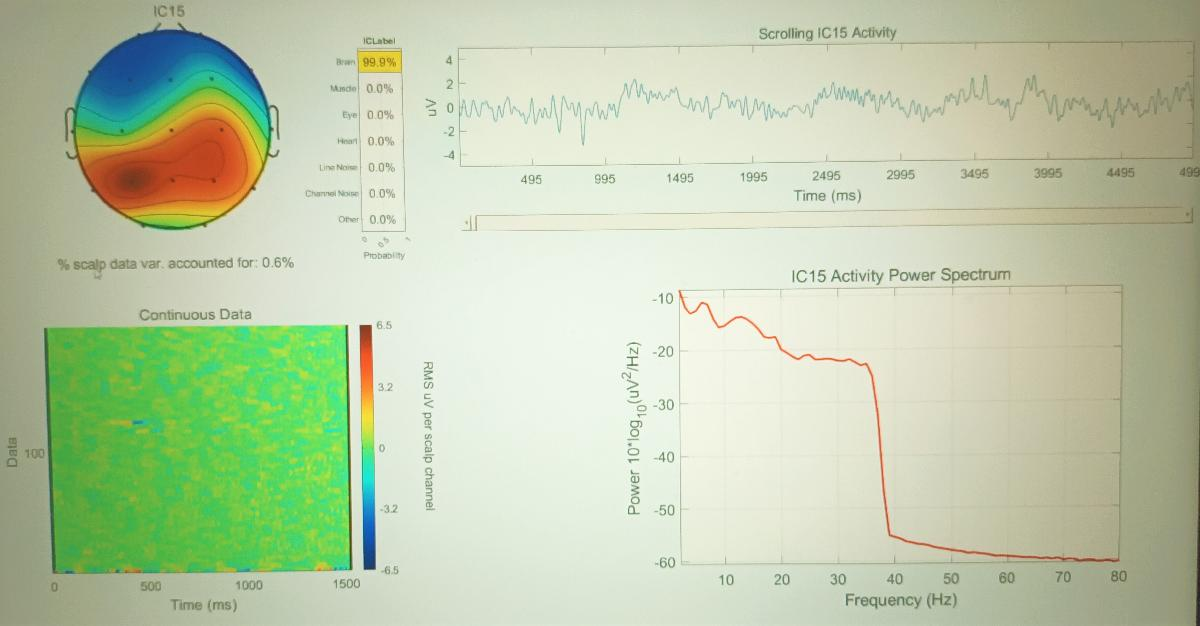

%      epoching
     a = EEG.data(1,1:240000);
b = reshape(a,[1 2000 120]);
for i=2:1:19
  a = EEG.data(i,1:240000);
  b = cat(1,b,reshape(a,[1 2000 120]));
end
b = b(:,1401:2000,:);
save Subject02_trials.mat b
%       deniosing
EEG.etc.eeglabvers = '2023.0'; % this tracks which version of EEGLAB is being used, you may ignore it
     EEG = pop_importdata('dataformat','matlab','nbchan',0,'data','C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\Subject02_trials.mat','srate',200,'pnts',0,'xmin',0);

pop_editset(): raw data file 'C:\\Users\\HAMAHANG\\Desktop\\sut\\S4\\SS\\PROJECT\\workplace\\eeglab2023.0\\Subject02_trials.mat' found
eeg_checkset warning: number of columns in data (19) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (120) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (600) does not match the number of points (0): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames


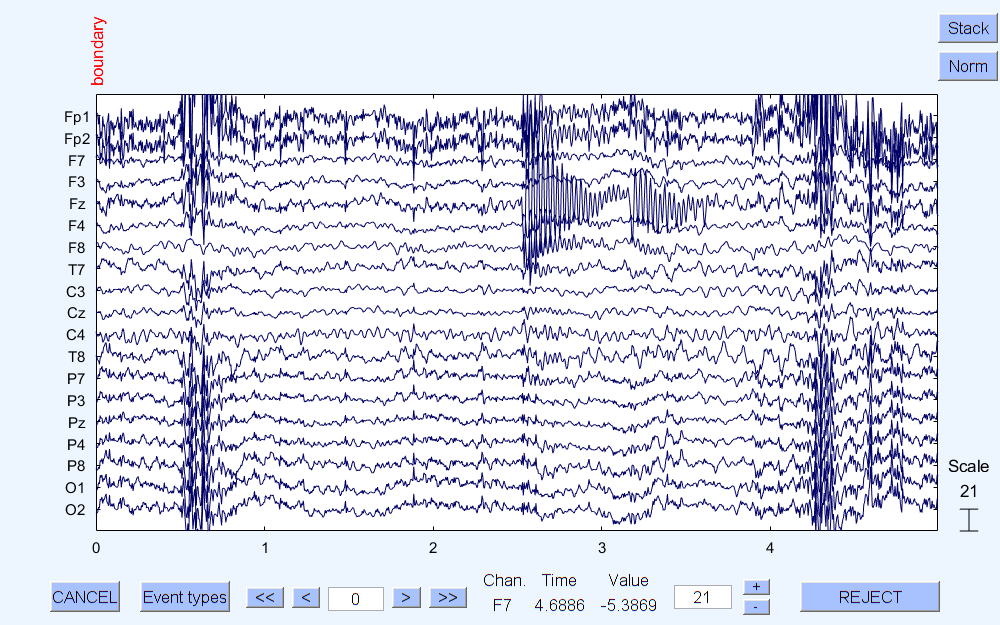

     EEG.setname='imported0201';
%      denoising excecution
     EEG.setname='imported0201_selected';
     EEG = eeg_checkset( EEG );
     EEG=pop_chanedit(EEG, []);

     EEG = pop_select( EEG, 'channel',{'Fp1','Fz','Cz','Pz'});

Removing 15 channel(s)...


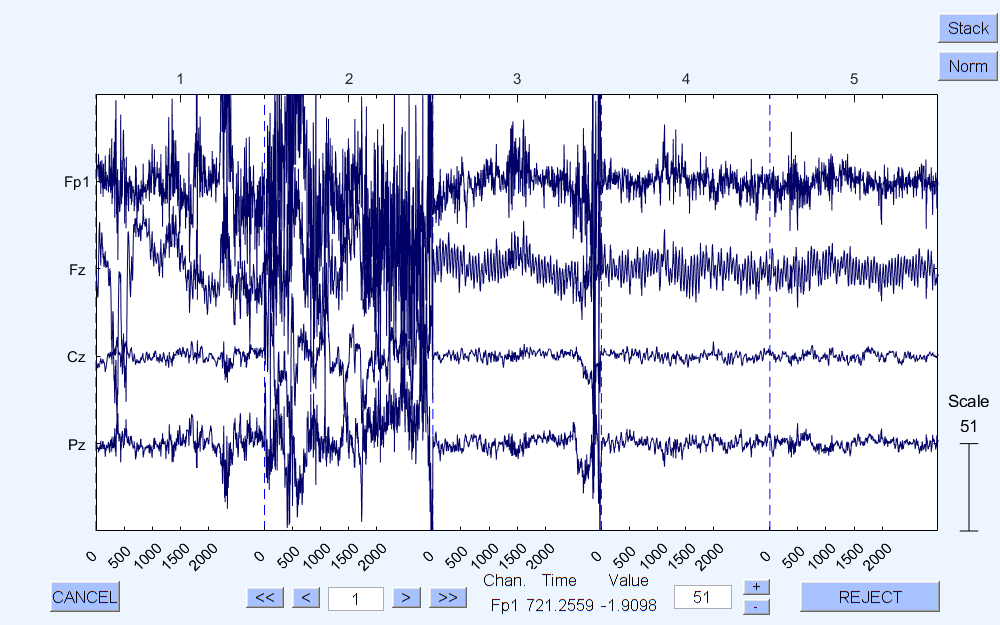

     EEG.setname='imported0201_selected_subbed';     
     EEG = eeg_checkset( EEG );
     pop_eegplot( EEG, 1, 1, 1);

### Phase locking value

Lachaux and colleagues proposed a functional connectivity metric known as phase locking value , that depends on the instantaneous phase of the signals. The underlying assumption here is that if two brain regions are functionally connected, then the difference between the instantaneous phases of the signals from these brain regions should remain more or less constant. Since, instantaneous phase (see below) has physical interpretation only for narrowband signals, the first step in computing the Phase Locking Value or PLV is filtering. Given multiple trials or epochs of narrowband filtered brain signals from two EEG channels

 the phase locking value can be defined as

                                                                    

Where N is the number of trials and theta(t,n) is the difference between the instantaneous phase of the two signals at time t and trial n. Thus computing PLV requires first filtering the data in the frequency band of interest and then extracting the instantaneous phase via Hilbert transform, which transforms the real signals into a complex representation. PLV takes values in the range of [0, 1] where a PLV of 0 implies that there is no phase synchrony and a PLV of 1 implies that the relative phase between the two signals is identical across the trials.

In order to find PLV values that are statistically significant, surrogates can be used, where trials are shuffled in one of the channels. The figure below summarizes this procedure.

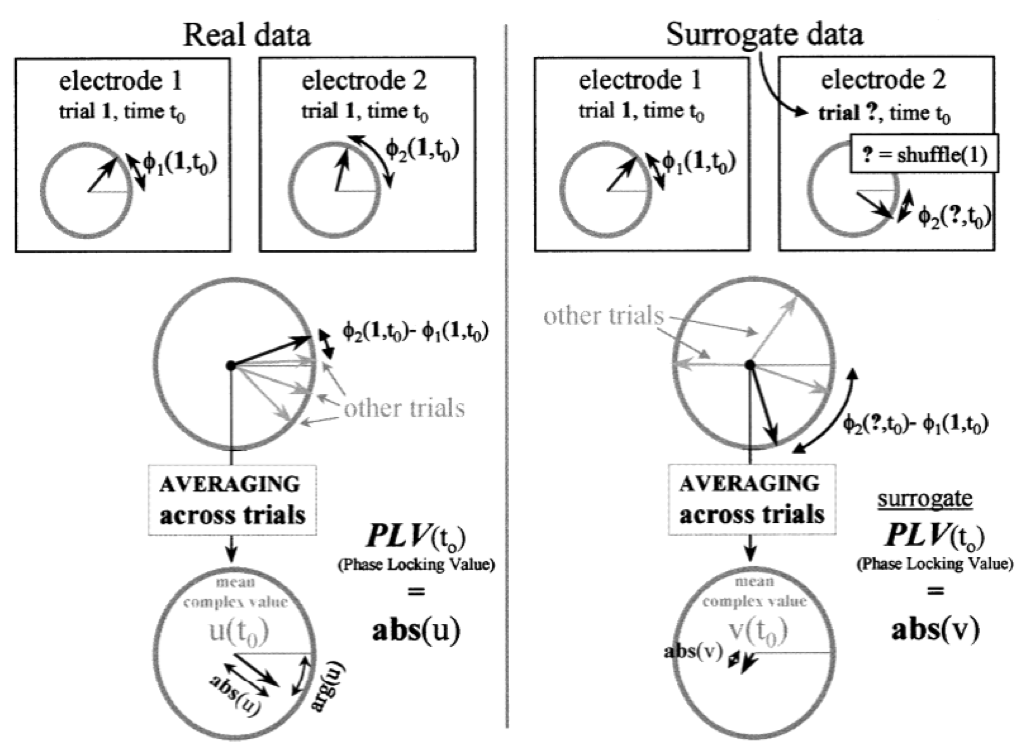

 delivered function is 'calculatePLV'

source:

https://sapienlabs.org/phase-locking-value/

## Result

### Values

% plv calculation for AD patients
load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\AD.mat
load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Normal.mat
AD_PLV = zeros(13,2,1);
for i=1:13
    pat_tri=AD(i).epoch;
    pat_odr=AD(i).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
AD_PLV(i,1,1)=AD_PLV(i,1,1)+calculatePLV(fz,cz,200,[35 40]);
    end
    AD_PLV(i,1,1) = AD_PLV(i,1,1)/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
AD_PLV(i,2,1)=AD_PLV(i,2,1)+calculatePLV(fz,cz,200,[35 40]);
    end
    AD_PLV(i,2,1) = AD_PLV(i,2,1)/size(pat_ros,1);
end
% plv calculation for normal patients
Nrm_PLV = zeros(15,2,1);
for i=1:15
    pat_tri=normal(i).epoch;
    pat_odr=normal(i).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
Nrm_PLV(i,1,1)=Nrm_PLV(i,1,1)+calculatePLV(fz,cz,200,[35 40]);
    end
    Nrm_PLV(i,1,1) = Nrm_PLV(i,1,1)/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
Nrm_PLV(i,2,1)=Nrm_PLV(i,2,1)+calculatePLV(fz,cz,200,[35 40]);
    end
    Nrm_PLV(i,2,1) = Nrm_PLV(i,2,1)/size(pat_ros,1);
end
save AD_PLV.mat AD_PLV
save Nrm_PLV.mat Nrm_PLV

### Distributions

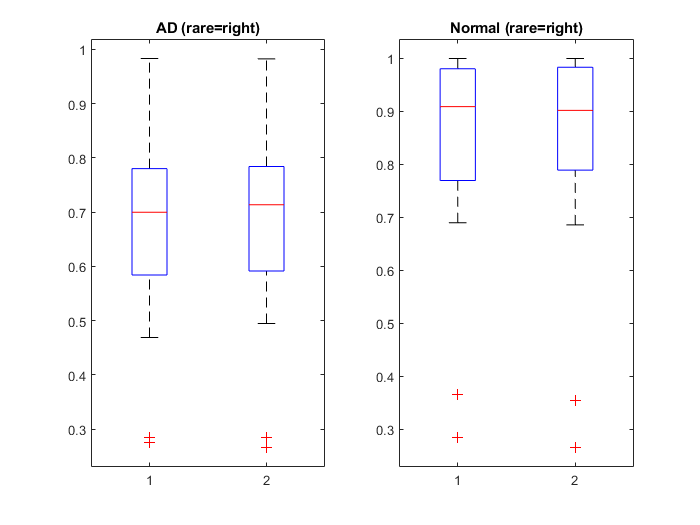

figure
load AD_PLV.mat
load Nrm_PLV.mat
subplot(1,2,1)
boxplot(AD_PLV)
title('AD (rare=right)')
subplot(1,2,2)
boxplot(Nrm_PLV)
title('Normal (rare=right)')

signal = AD_PLV(:,1); 
figure
% Fit a normal distribution to the signal
    pd = fitdist(signal, 'Normal');
fprintf('mu = %f\nsigma = %f',pd.mu,pd.sigma);

mu = 0.666146
sigma = 0.219650

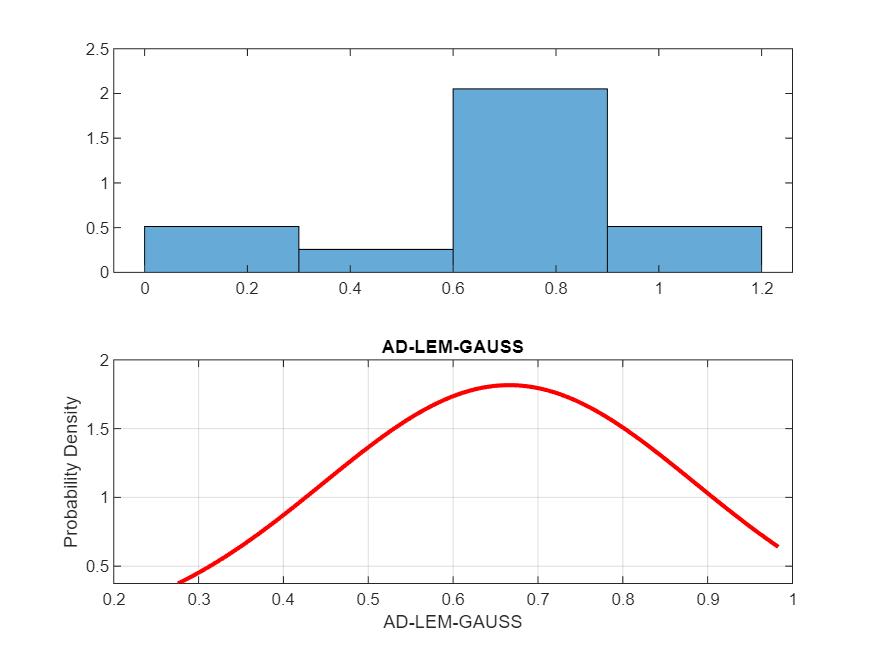

    % Generate x-values for the plot based on the range of the signal
    x = linspace(min(signal), max(signal), 100);

    % Compute the probability density function (PDF) values for the fitted distribution
    y = pdf(pd, x);
    subplot(2,1,1)
    % Plot the signal histogram and the fitted normal distribution PDF
    histogram(signal, 'Normalization', 'pdf', 'BinMethod', 'auto');
    subplot(2,1,2)
    plot(x, y, 'r', 'LineWidth', 2);

    % Add labels  
    xlabel('AD-LEM-GAUSS');
    ylabel('Probability Density');

    % Adjust plot aesthetics if desired
    grid on;
    title('AD-LEM-GAUSS');

    signal = AD_PLV(:,2);
    % Fit a normal distribution to the signal
    pd = fitdist(signal, 'Normal');
    fprintf('mu = %f\nsigma = %f',pd.mu,pd.sigma);

mu = 0.668252
sigma = 0.218533

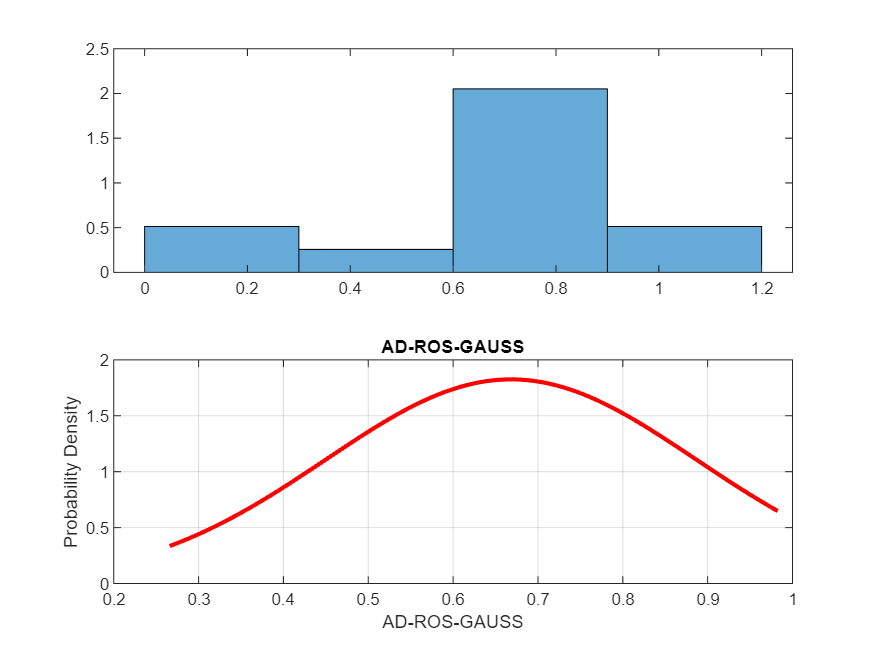

figure
    % Generate x-values for the plot based on the range of the signal
    x = linspace(min(signal), max(signal), 100);

    % Compute the probability density function (PDF) values for the fitted distribution
    y = pdf(pd, x);
    subplot(2,1,1)
    % Plot the signal histogram and the fitted normal distribution PDF
    histogram(signal, 'Normalization', 'pdf', 'BinMethod', 'auto');
    subplot(2,1,2)
    plot(x, y, 'r', 'LineWidth', 2);
    title('AD-ROS-GAUSS');
    % Add labels  
    xlabel('AD-ROS-GAUSS');
    ylabel('Probability Density');

    % Adjust plot aesthetics if desired
    grid on;

    signal = Nrm_PLV(:,1);
    % Fit a normal distribution to the signal
    pd = fitdist(signal, 'Normal');
    fprintf('mu = %f\nsigma = %f',pd.mu,pd.sigma);

mu = 0.822297
sigma = 0.222015

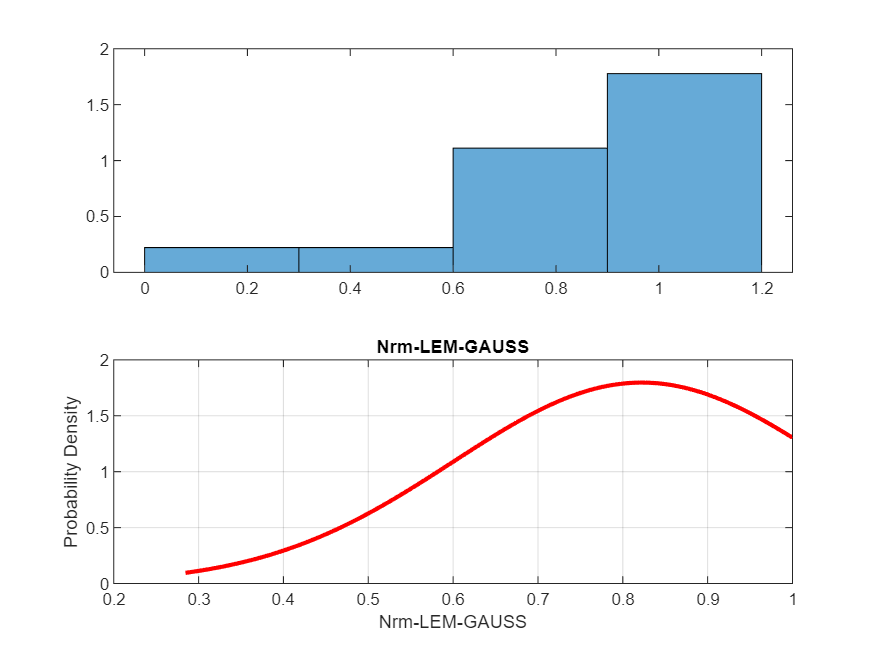

figure
    % Generate x-values for the plot based on the range of the signal
    x = linspace(min(signal), max(signal), 100);

    % Compute the probability density function (PDF) values for the fitted distribution
    y = pdf(pd, x);
    subplot(2,1,1)
    % Plot the signal histogram and the fitted normal distribution PDF
    histogram(signal, 'Normalization', 'pdf', 'BinMethod', 'auto');
    subplot(2,1,2)
    plot(x, y, 'r', 'LineWidth', 2);

    % Add labels  
    xlabel('Nrm-LEM-GAUSS');
    ylabel('Probability Density');

    % Adjust plot aesthetics if desired
    grid on;
    title('Nrm-LEM-GAUSS');

    signal = Nrm_PLV(:,2);
    % Fit a normal distribution to the signal
    pd = fitdist(signal, 'Normal');
    fprintf('mu = %f\nsigma = %f',pd.mu,pd.sigma);

mu = 0.820636
sigma = 0.226607

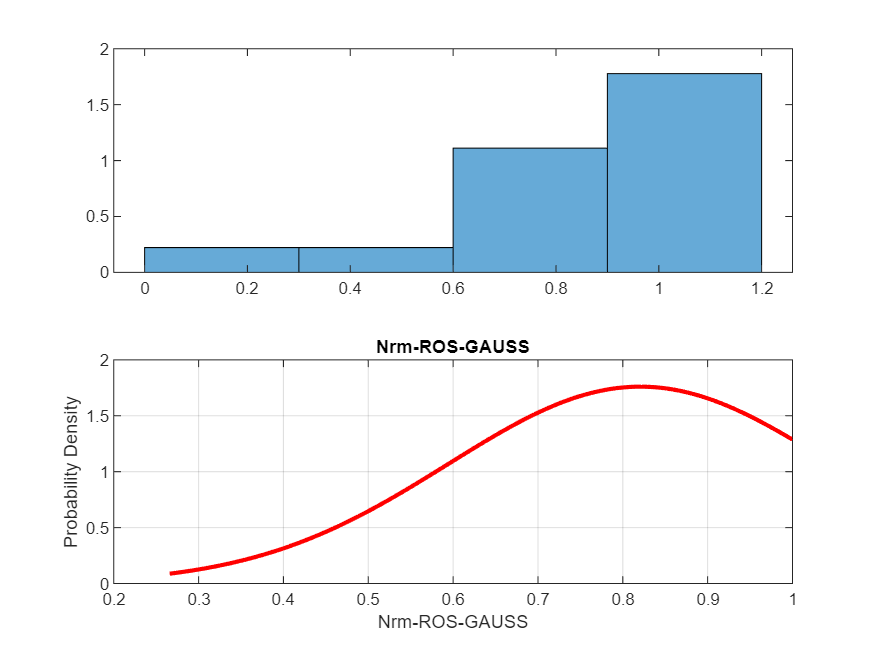

figure
    % Generate x-values for the plot based on the range of the signal
    x = linspace(min(signal), max(signal), 100);

    % Compute the probability density function (PDF) values for the fitted distribution
    y = pdf(pd, x);
    subplot(2,1,1)
    % Plot the signal histogram and the fitted normal distribution PDF
    histogram(signal, 'Normalization', 'pdf', 'BinMethod', 'auto');
    subplot(2,1,2)
    plot(x, y, 'r', 'LineWidth', 2);

    % Add labels  
    xlabel('Nrm-ROS-GAUSS');
    ylabel('Probability Density');

    % Adjust plot aesthetics if desired
    grid on;
    title('Nrm-ROS-GAUSS');

the null hypothesis is  mu1 - mu2 = 0 as the 'ttest2' works with

    % Perform two-sample t-test for lemmon odor
[~, p] = ttest2(AD_PLV(:,1), Nrm_PLV(:,1));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('lemmon p-value = %f',p)

lemmon p-value = 0.073472

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


    % Perform two-sample t-test for rose odor
[~, p] = ttest2(AD_PLV(:,2), Nrm_PLV(:,2));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('rose p-value = %f',p)

rose p-value = 0.082832

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


### Statistical Significance

- After implying ttest2 on the data provided for each group (for significance level of 0.05) we can declare:

we can't reject the null hypothesis on both cases which consisted of two lemmon groups and two rose groups.

in other words, 

There is no significant difference between the means of the AD(lemmon-rose) and Normal(lemmon-rose) data

### Phase Difference

#### random subjects

note that phase here represents hilbert transform phase

As you can see via the polar histograms,phase difference of a pair of channels which belong to an AD patient is wider then a Normal patient(eather single or multiple).

this could be interpreted as EEG synchronization.generally speaking, brain signals of a normal healthy person are much alike.contradictory,

brain signals of an AD person suffers from Asynchronization and vary from an area to another. 

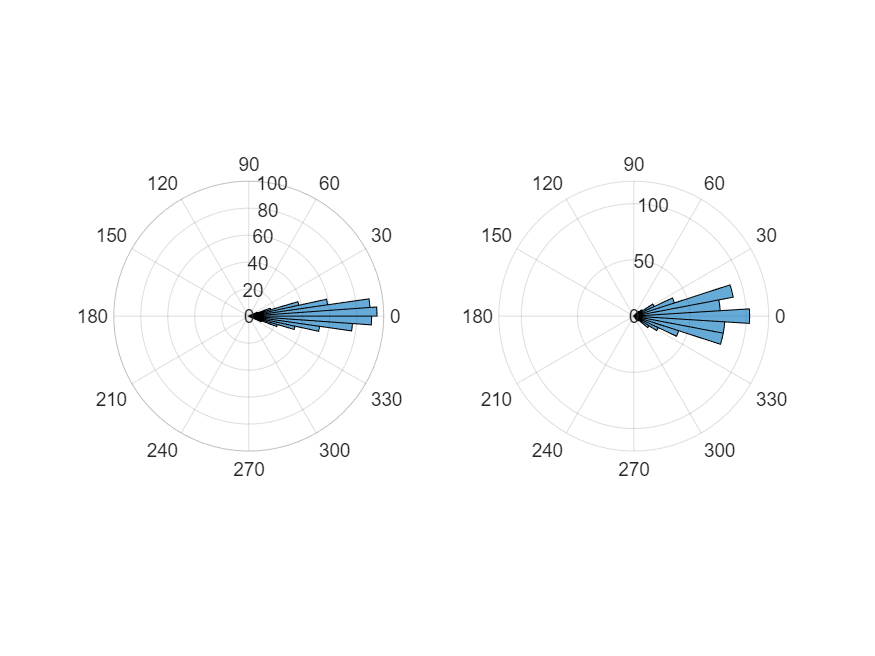

% phase difference calculation for a random AD patient
load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\AD.mat
load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Normal.mat
p = randi(13);
AD_Ph_diff_lem= 0;
AD_Ph_diff_ros= 0;
    pat_tri=AD(p).epoch;
    pat_odr=AD(p).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
AD_Ph_diff_lem=AD_Ph_diff_lem+phaseCAL(fz,cz,200,[35 40]);
    end
    AD_Ph_diff_lem = AD_Ph_diff_lem/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
AD_Ph_diff_ros=AD_Ph_diff_ros+phaseCAL(fz,cz,200,[35 40]);
    end
    AD_Ph_diff_ros = AD_Ph_diff_ros/size(pat_ros,1);
    figure 
    subplot(1,2,1)
polarhistogram(AD_Ph_diff_lem);
    subplot(1,2,2)
polarhistogram(AD_Ph_diff_ros);

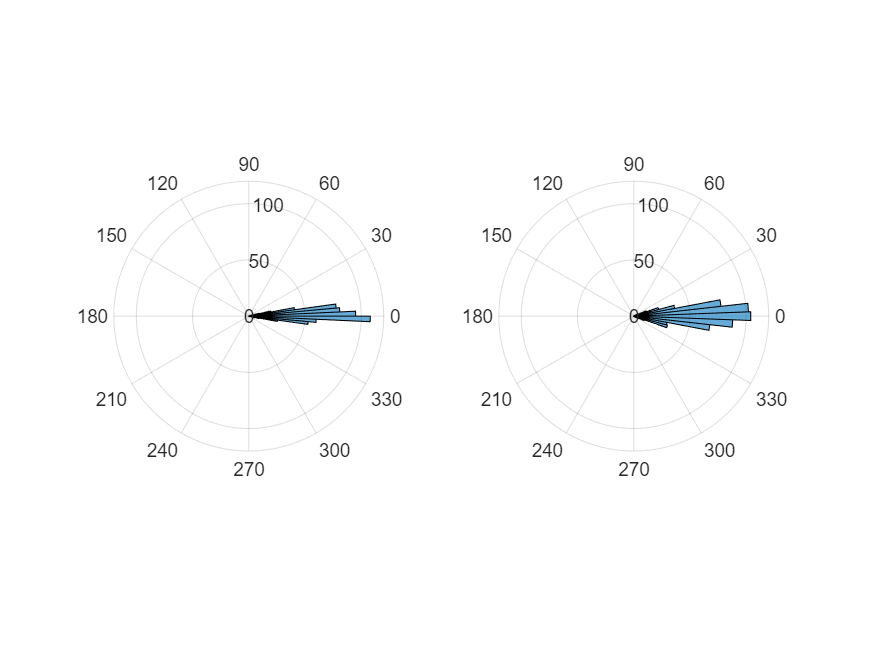

    % phase difference calculation for a random Normal patient
    p = randi(15);
Nrm_Ph_diff_lem= 0;
Nrm_Ph_diff_ros= 0;
    pat_tri=normal(p).epoch;
    pat_odr=normal(p).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr);
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
Nrm_Ph_diff_lem=Nrm_Ph_diff_lem+phaseCAL(fz,cz,200,[35 40]);
    end
    Nrm_Ph_diff_lem = Nrm_Ph_diff_lem/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
Nrm_Ph_diff_ros=Nrm_Ph_diff_ros+phaseCAL(fz,cz,200,[35 40]);
    end
    Nrm_Ph_diff_ros = Nrm_Ph_diff_ros/size(pat_ros,1);
    figure 
    subplot(1,2,1)
polarhistogram(Nrm_Ph_diff_lem);
    subplot(1,2,2)
polarhistogram(Nrm_Ph_diff_ros);

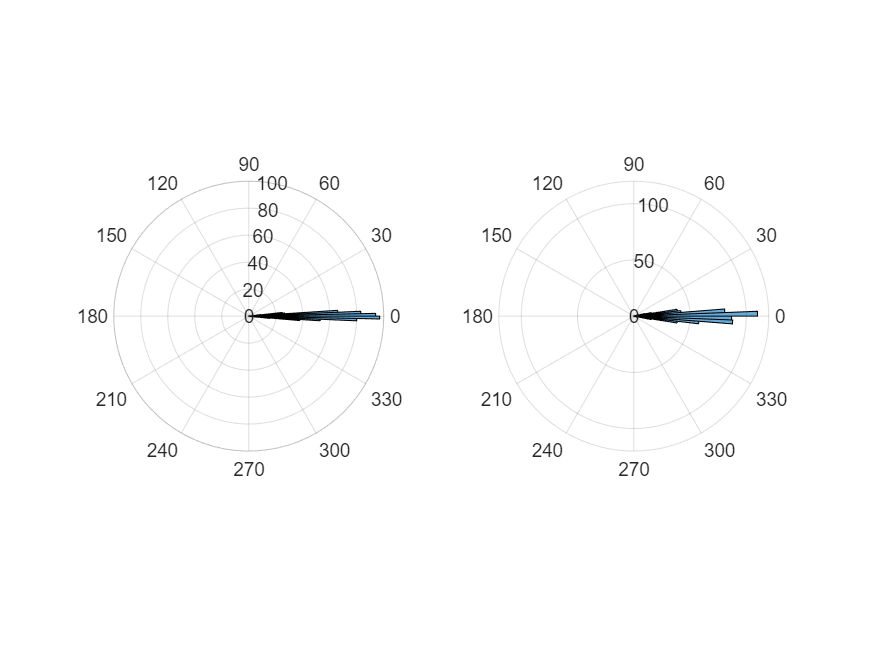

% phase difference calculation for all AD patients
AD_Ph_diff_lem_all= 0;
AD_Ph_diff_ros_all= 0;
for i=1:13
AD_Ph_diff_lem= 0;
AD_Ph_diff_ros= 0;
    pat_tri=AD(i).epoch;
    pat_odr=AD(i).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
AD_Ph_diff_lem=AD_Ph_diff_lem+phaseCAL(fz,cz,200,[35 40]);
    end
    AD_Ph_diff_lem = AD_Ph_diff_lem/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
AD_Ph_diff_ros=AD_Ph_diff_ros+phaseCAL(fz,cz,200,[35 40]);
    end
    AD_Ph_diff_ros = AD_Ph_diff_ros/size(pat_ros,1);
    AD_Ph_diff_lem_all = AD_Ph_diff_lem_all + AD_Ph_diff_lem;
    AD_Ph_diff_ros_all = AD_Ph_diff_ros_all +AD_Ph_diff_ros;
end
AD_Ph_diff_lem_all = AD_Ph_diff_lem_all/13;
AD_Ph_diff_ros_all = AD_Ph_diff_ros_all/13;
save AD_Ph_diff_lem_all.mat AD_Ph_diff_lem_all
save AD_Ph_diff_ros_all.mat AD_Ph_diff_ros_all
load AD_Ph_diff_lem_all.mat
load AD_Ph_diff_ros_all.mat
    figure 
    subplot(1,2,1)
polarhistogram(AD_Ph_diff_lem_all);
    subplot(1,2,2)
polarhistogram(AD_Ph_diff_ros_all);

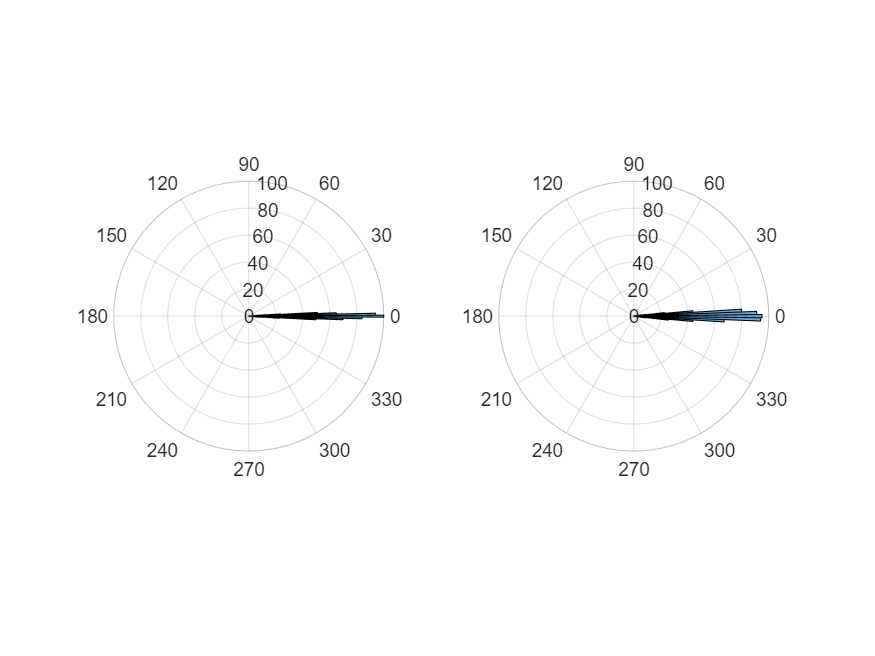

% phase difference calculation for all normal patients
Nrm_Ph_diff_lem_all= 0;
Nrm_Ph_diff_ros_all= 0;
for i=1:15
Nrm_Ph_diff_lem= 0;
Nrm_Ph_diff_ros= 0;
    pat_tri=normal(i).epoch;
    pat_odr=normal(i).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
fz = pat_tri_lem(2,:,j);
cz = pat_tri_lem(3,:,j);
Nrm_Ph_diff_lem=Nrm_Ph_diff_lem+phaseCAL(fz,cz,200,[35 40]);
    end
    Nrm_Ph_diff_lem = Nrm_Ph_diff_lem/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
fz = pat_tri_ros(2,:,j);
cz = pat_tri_ros(3,:,j);
Nrm_Ph_diff_ros=Nrm_Ph_diff_ros+phaseCAL(fz,cz,200,[35 40]);
    end
    Nrm_Ph_diff_ros = Nrm_Ph_diff_ros/size(pat_ros,1);
    Nrm_Ph_diff_lem_all = Nrm_Ph_diff_lem_all + Nrm_Ph_diff_lem;
    Nrm_Ph_diff_ros_all = Nrm_Ph_diff_ros_all +Nrm_Ph_diff_ros;
end
Nrm_Ph_diff_lem_all = Nrm_Ph_diff_lem_all/15;
Nrm_Ph_diff_ros_all = Nrm_Ph_diff_ros_all/15;
save Nrm_Ph_diff_lem_all.mat Nrm_Ph_diff_lem_all
save Nrm_Ph_diff_ros_all.mat Nrm_Ph_diff_ros_all
load Nrm_Ph_diff_lem_all.mat
load Nrm_Ph_diff_ros_all.mat
    figure 
    subplot(1,2,1)
polarhistogram(Nrm_Ph_diff_lem_all);
    subplot(1,2,2)
polarhistogram(Nrm_Ph_diff_ros_all);

### Heatmaps 

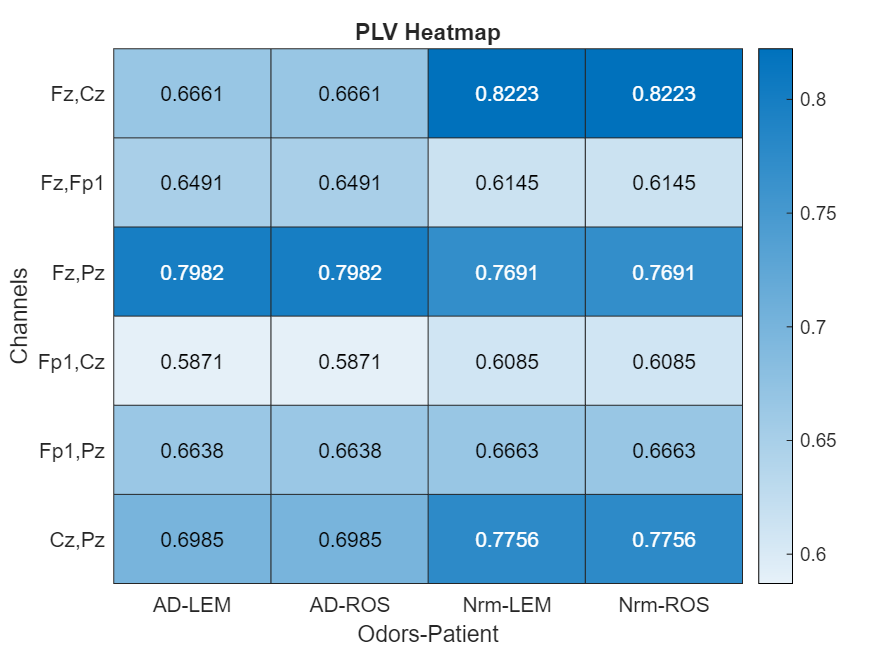

% load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\AD.mat
% load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Normal.mat
% % case 1:Fz,Cz
% AD_PLV_CH1_CH2 = zeros(6,2);
% AD_PLV_CH1_CH2(1,[1 2]) = extendedPLV(AD,13,2,3); 
% Nrm_PLV_CH1_CH2 = zeros(6,2);
% Nrm_PLV_CH1_CH2(1,[1 2]) = extendedPLV(normal,15,2,3);
% % case 2:Fz,Fp1
% AD_PLV_CH1_CH2(2,[1 2]) = extendedPLV(AD,13,1,2);
% Nrm_PLV_CH1_CH2(2,[1 2]) = extendedPLV(normal,15,1,2);
% % case 3:Fz,Pz
% AD_PLV_CH1_CH2(3,[1 2]) = extendedPLV(AD,13,2,4); 
% Nrm_PLV_CH1_CH2(3,[1 2]) = extendedPLV(normal,15,2,4);
% % case 4:Fp1,Cz
% AD_PLV_CH1_CH2(4,[1 2]) = extendedPLV(AD,13,1,3); 
% Nrm_PLV_CH1_CH2(4,[1 2]) = extendedPLV(normal,15,1,3);
% % case 5:Fp1,Pz
% AD_PLV_CH1_CH2(5,[1 2]) = extendedPLV(AD,13,1,4); 
% Nrm_PLV_CH1_CH2(5,[1 2]) = extendedPLV(normal,15,1,4);
% % case 6:Pz,Cz
% AD_PLV_CH1_CH2(6,[1 2]) = extendedPLV(AD,13,3,4); 
% Nrm_PLV_CH1_CH2(6,[1 2]) = extendedPLV(normal,15,3,4);
figure
load AD_PLV_CH1_CH2.mat
load Nrm_PLV_CH1_CH2.mat
cdata = cat(2,AD_PLV_CH1_CH2,Nrm_PLV_CH1_CH2);
xvalues = {'AD-LEM','AD-ROS','Nrm-LEM','Nrm-ROS'};
yvalues = {'Fz,Cz','Fz,Fp1','Fz,Pz','Fp1,Cz','Fp1,Pz','Cz,Pz'};
h = heatmap(xvalues,yvalues,cdata);
h.Title = 'PLV Heatmap';
h.XLabel = 'Odors-Patient';
h.YLabel = 'Channels';

#### testing

The result p is `1` if the test rejects the null hypothesis at the 5% significance level, and `0` otherwise.

for the null hypothesis that the data in `x` comes from a normal distribution with mean `m` and unknown variance

% % p value lemmon ad
p = ttest(AD_PLV_CH1_CH2(:,1),AD_PLV_CH1_CH2(1,1));
if p == 0
    disp('Reject the null hypothesis.');
else
    disp('Fail to reject the null hypothesis.');
end

Reject the null hypothesis.


% % p value rose ad
p = ttest(AD_PLV_CH1_CH2(:,2),AD_PLV_CH1_CH2(1,2));
if p == 0
    disp('Reject the null hypothesis.');
else
    disp('Fail to reject the null hypothesis.');
end

Reject the null hypothesis.


% % p value lemmon nrm
p = ttest(Nrm_PLV_CH1_CH2(:,1),Nrm_PLV_CH1_CH2(1,1));
if p == 0
    disp('Reject the null hypothesis.');
else
    disp('Fail to reject the null hypothesis.');
end

Fail to reject the null hypothesis.


% % p value rose nrm
p = ttest(Nrm_PLV_CH1_CH2(:,2),Nrm_PLV_CH1_CH2(1,2));
if p == 0
    disp('Reject the null hypothesis.');
else
    disp('Fail to reject the null hypothesis.');
end

Fail to reject the null hypothesis.


## Bonus*

### Additional information

**Background/aim:** Mild cognitive impairment (MCI) is defined as a pathological stage between 'healthy aging' and 'dementia' In this study, cases of MCI were compared with early-stage Alzheimer disease (AD) and age-related cognitive decline (ARCD) in terms of cognitive profiles in order to find a connection between MCI and AD.

**Materials and methods:** Patients who were comparable in terms of age and sex and who met the criteria of MCI, ARCD, or early-stage AD were included in the study retrospectively. Wechsler memory scale, executive function, visuospatial, language, and memory tests were applied to all subjects. Additionally, all patients completed a mini-mental state examination test, geriatric depression scale, and activities of daily living scale.

**Results:** Complex attention tests and long-term memory tests were more impaired in MCI patients when compared with ARCD. However, there were no significant differences between the MCI and ARCD cases in activities of daily living. Memory and executive functions were more deteriorated in patients with AD in comparison to MCI.

**Conclusion:** During the follow-up period of ARCD, impairment in orientation, complex attention, and long-term memory should suggest the diagnosis of MCI. When personal information and executive functions are affected in MCI, AD should be carefully considered.

Researchers have found that more people with MCI than those without it go on to develop Alzheimer's disease or a related dementia. An estimated 10 to 20% of people age 65 or older with MCI develop dementia over a one-year period. However, not everyone who has MCI develops. 

### MCI Data Processing 

Brain about to retire:

observable on the box plots below,the phase locking value(PLV) which represents brain signals synchrony declines with dementia severy,

simply saying,the more Asynchrony the harder problem!

NOTE:null hypothesis on ttesting suggests that m2=>m1

- What is kruskal wallis test?

The Kruskal-Wallis test is a non-parametric statistical test used to compare the medians of three or more independent groups. It is an extension of the Mann-Whitney U-test, which is used to compare two independent groups.

The Kruskal-Wallis test is typically employed when the assumptions of normality and equal variances required by the parametric analysis of variance (ANOVA) cannot be met. Instead of comparing means, the test examines the ranks or orders of the observations within each group to determine if there are differences in the distributions.

Here's a brief overview of how the Kruskal-Wallis test works:

1. Null Hypothesis (H0): The populations from which the groups are sampled have the same medians.

2. Alternative Hypothesis (HA): At least one group has a different median compared to the others.

3. Rank the data: Pool all observations from the different groups and assign ranks to each value. Ties are given an average rank.

4. Calculate the Kruskal-Wallis test statistic: This statistic examines the differences in ranked data among the groups. It estimates the degree to which the observed differences in the medians are greater than would be expected by chance.

5. Compute the p-value: The test statistic is compared to the chi-squared distribution to obtain a p-value. The p-value represents the probability of observing such extreme differences in the medians under the assumption that the null hypothesis is true. A small p-value (typically below a chosen significance level like 0.05) indicates evidence to reject the null hypothesis in favor of the alternative hypothesis.

If the null hypothesis is rejected, there is evidence that at least one group has a different median compared to the others. However, the Kruskal-Wallis test does not determine which specific groups differ from each other. To investigate further, post-hoc tests (e.g., pairwise comparisons) can be conducted.

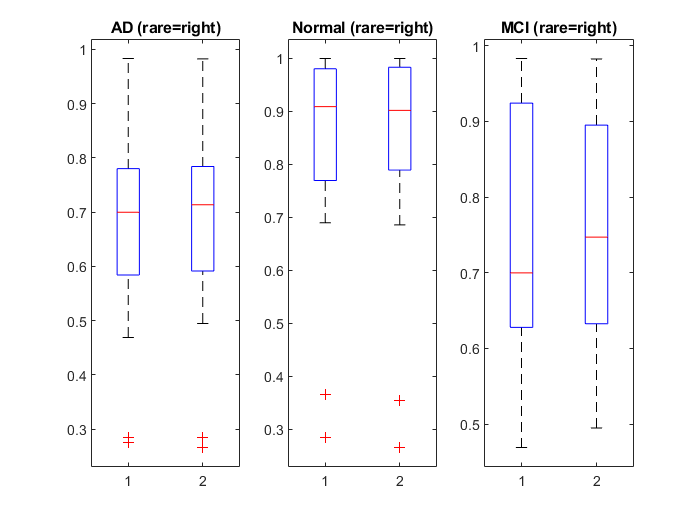

% load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\MCI.mat
load AD_PLV.mat
load Nrm_PLV.mat
% MCI_PLV = zeros(7,2,1);
% for i=1:7
%     pat_tri=AD(i).epoch;
%     pat_odr=AD(i).odor;
%     pat_lem=find(~pat_odr);
%     pat_ros=find(pat_odr); 
%     pat_tri_lem=pat_tri(:,:,pat_lem);
%     pat_tri_ros=pat_tri(:,:,pat_ros);
%     for j=1:size(pat_lem,1)
% fz = pat_tri_lem(2,:,j);
% cz = pat_tri_lem(3,:,j);
% MCI_PLV(i,1,1)=MCI_PLV(i,1,1)+calculatePLV(fz,cz,200,[35 40]);
%     end
%     MCI_PLV(i,1,1) = MCI_PLV(i,1,1)/size(pat_lem,1);    
%     for j=1:size(pat_ros,1)
% fz = pat_tri_ros(2,:,j);
% cz = pat_tri_ros(3,:,j);
% MCI_PLV(i,2,1)=MCI_PLV(i,2,1)+calculatePLV(fz,cz,200,[35 40]);
%     end
%     MCI_PLV(i,2,1) = MCI_PLV(i,2,1)/size(pat_ros,1);
% end
% save MCI_PLV.mat MCI_PLV
load MCI_PLV.mat 
figure
subplot(1,3,1)
boxplot(AD_PLV)
title('AD (rare=right)')
subplot(1,3,2)
boxplot(Nrm_PLV)
title('Normal (rare=right)')
subplot(1,3,3)
boxplot(MCI_PLV)
title('MCI (rare=right)')

    % Perform two-sample t-test for lemmon odor between Normal and MCI
[~, p] = ttest2(Nrm_PLV(:,1), MCI_PLV(:,1));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('rose p-value = %f',p)

rose p-value = 0.398368

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


    % Perform two-sample t-test for rose odor between Normal and MCI
[~, p] = ttest2(Nrm_PLV(:,2), MCI_PLV(:,2));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('rose p-value = %f',p)

rose p-value = 0.428548

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


    % Perform two-sample t-test for lemmon odor between AD and MCI
[~, p] = ttest2(MCI_PLV(:,1),AD_PLV(:,2));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('rose p-value = %f',p)

rose p-value = 0.483556

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


    % Perform two-sample t-test for rose odor between AD and MCI
[~, p] = ttest2( MCI_PLV(:,2),AD_PLV(:,2));
% Compare p-value to significance level
significance_level = 0.05;
fprintf('rose p-value = %f',p)

rose p-value = 0.451521

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


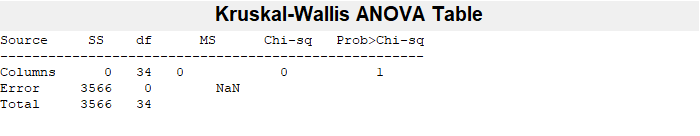

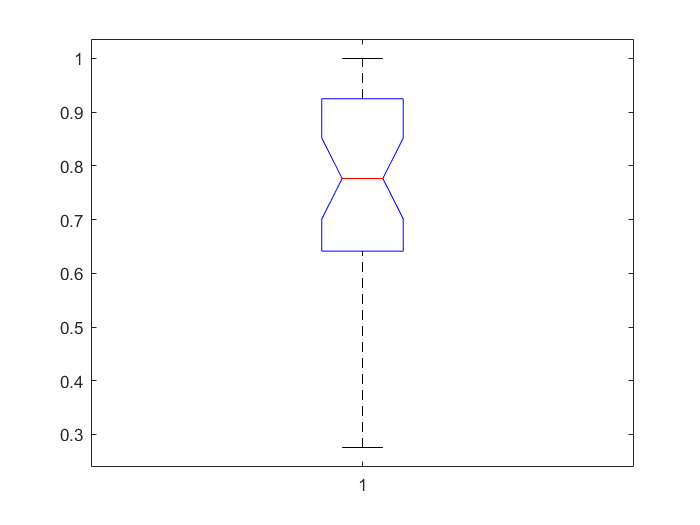

significance_level = 0.05;
lem_all = cat(2,transpose(AD_PLV(:,1)),transpose(Nrm_PLV(:,1)),transpose(MCI_PLV(:,1)));
% Perform Kruskal-Wallis test for lemmon
[p, tbl, stats] = kruskalwallis(lem_all, [], 'on');  % 'on' disables display

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


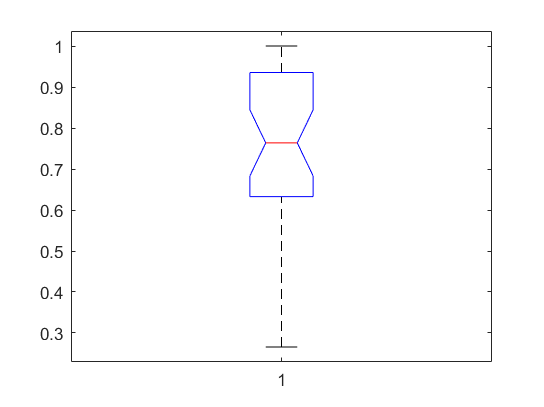

ros_all = cat(2,transpose(AD_PLV(:,2)),transpose(Nrm_PLV(:,2)),transpose(MCI_PLV(:,2)));
% Perform Kruskal-Wallis test for rose 
[p, tbl, stats] = kruskalwallis(ros_all, [], 'on');  % 'on' disables display

if p < significance_level
    disp('Reject the null hypothesis. There is a significant difference between the means.');
else
    disp('Fail to reject the null hypothesis. There is no significant difference between the means.');
end

Fail to reject the null hypothesis. There is no significant difference between the means.


### Phase-Amplitude Coupling (PAC)

####  Metrics 

Phase-Amplitude Coupling (PAC) measures characterize the relationship between the phase of one oscillatory signal and the amplitude of another oscillatory signal. PAC is a phenomenon observed in brain activity, particularly in neural oscillations measured using electroencephalography (EEG) or magnetoencephalography (MEG).

In PAC, the amplitude of a low-frequency oscillation (referred to as the "carrier" or "envelope") is modulated by the phase of a higher-frequency oscillation (referred to as the "modulator"). PAC is often observed when the modulator frequency is in the gamma range (30-100 Hz) and the carrier frequency is in a lower frequency band, such as theta (4-8 Hz), alpha (8-12 Hz), or beta (12-30 Hz).

PAC is typically quantified using different measures. Here are some commonly used PAC measures: Modulation Index (MI),Concentration Parameter (Kappa),Phase Locking Value (PLV) and  Cross-Frequency Coherence (CFC)

in this section we describe Modulation Index (MI) and Cross-Frequency Coherence (CFC)

- Modulation Index (MI): The MI measures the strength of coupling between the phase of the modulator and the amplitude of the carrier. It is calculated as the difference between the mean amplitude within one phase bin and the mean amplitude across all phase bins, normalized by the mean amplitude across all phase bins.

- Cross-Frequency Coherence (CFC): CFC measures the coherence between the modulator and carrier oscillations across multiple frequencies. It evaluates how the phase of the modulator oscillation relates to the amplitude of the carrier oscillation at different frequency ranges.

#### Implementation

#### Modulation Index (MI)

As you can investigate via boxplots,the coherance of channel fz and cz increases for normal patients which somehow states that brain signals of a normal person

are more or less coupled and modulate and carry towards each another,while for AD patiens coupling declines overall.

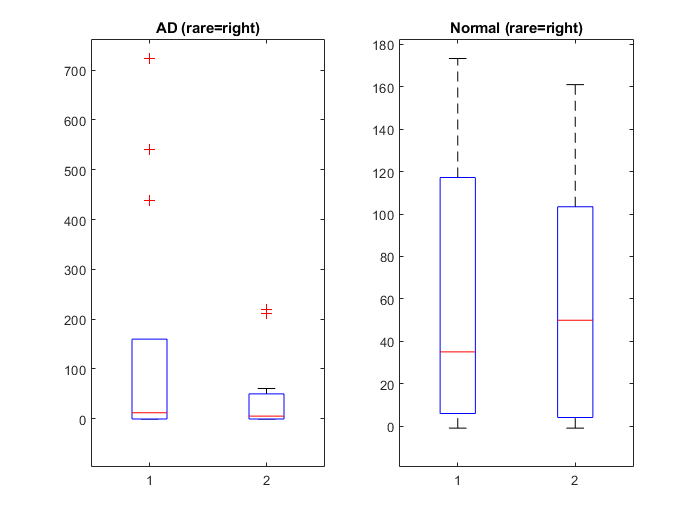

load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\AD.mat
load C:\Users\HAMAHANG\Desktop\sut\S4\SS\PROJECT\workplace\Dataset\Dataset\Normal.mat
% MI calculation for AD Patients
% AD_MI = zeros(13,2,1);
% for i=1:13
%     pat_tri=AD(i).epoch;
%     pat_odr=AD(i).odor;
%     pat_lem=find(~pat_odr);
%     pat_ros=find(pat_odr); 
%     pat_tri_lem=pat_tri(:,:,pat_lem);
%     pat_tri_ros=pat_tri(:,:,pat_ros);
%     for j=1:size(pat_lem,1)
% fz = pat_tri_lem(2,:,j);
% cz = pat_tri_lem(3,:,j);
% AD_MI(i,1,1)=AD_MI(i,1,1)+MIcal(cz,fz);
%     end
%     AD_MI(i,1,1) = AD_MI(i,1,1)/size(pat_lem,1);    
%     for j=1:size(pat_ros,1)
% fz = pat_tri_ros(2,:,j);
% cz = pat_tri_ros(3,:,j);
% AD_MI(i,2,1)=AD_MI(i,2,1)+MIcal(cz,fz);
%     end
%  AD_MI(i,2,1) = AD_MI(i,2,1)/size(pat_ros,1);
% end
% % MI calculation for normal patients
% Nrm_MI = zeros(15,2,1);
% for i=1:15
%     pat_tri=normal(i).epoch;
%     pat_odr=normal(i).odor;
%     pat_lem=find(~pat_odr);
%     pat_ros=find(pat_odr); 
%     pat_tri_lem=pat_tri(:,:,pat_lem);
%     pat_tri_ros=pat_tri(:,:,pat_ros);
%     for j=1:size(pat_lem,1)
% fz = pat_tri_lem(2,:,j);
% cz = pat_tri_lem(3,:,j);
% Nrm_MI(i,1,1)=Nrm_MI(i,1,1)+MIcal(fz,cz);
%     end
%     Nrm_MI(i,1,1) = Nrm_MI(i,1,1)/size(pat_lem,1);    
%     for j=1:size(pat_ros,1)
% fz = pat_tri_ros(2,:,j);
% cz = pat_tri_ros(3,:,j);
% Nrm_MI(i,2,1)=Nrm_MI(i,2,1)+MIcal(fz,cz);
%     end
%     Nrm_MI(i,2,1) = Nrm_MI(i,2,1)/size(pat_ros,1);
% end
% save AD_MI.mat AD_MI
% save Nrm_MI.mat Nrm_MI
figure
load AD_PLV.mat
load Nrm_PLV.mat
subplot(1,2,1)
boxplot(AD_MI)
title('AD (rare=right)')
subplot(1,2,2)
boxplot(Nrm_MI)
title('Normal (rare=right)')

##  Conclusion 

In this project we have done these practices:

- Research and investigate

- Became familiar with electroencephalography and it's methods and properties

- How to use EEG lab for preprocessing signals distinguish noisy signal from clean signal

- We also got to know phase locking value or plv and it's functionality for comparing synchrony of various signals 

- The use of Hilbert transform for calculating plv 

- What is p-value and t-test and krusakl-wallis test and how can we use them for evaluating different hypothesis from a statistical significance point of view 

- The importance of phase difference and What could it stand for 

- Why isn't phase difference and plv of different kinds of patients isn't the same and establish an induction based on that 

- What is mild cognitive impairment or MCI could it lead to dementia Alzheimer disease or not 

- Examine a different piece of equipment which evaluates the brain signals synchrony

this was a brief describtion of what we did after all

i don't know how was the quality of my project but i know i tried my best!

further information about the findings are provided troughout the 'paper' :)

### MI Calculator

function MI = MIcal(data1,data2)
% Set the number of phase bins for the modulator signal
numBins = 12;  % Adjust the number of bins as desired
data1 = transpose(abs(data1));
data2 = transpose((data2));
% Compute the phase angles of the modulator signal
phase = angle(data1);  % Assuming data1 is the modulator signal

% Compute the instantaneous amplitude of the carrier signal
amplitude = abs(data2);  % Assuming data2 is the carrier signal

% Compute the Modulation Index (MI)
edges = linspace(-pi, pi, numBins+1);  % Define edges of the phase bins
binIndices = discretize(phase, edges);  % Assign each phase angle to a bin
binAmp = accumarray(binIndices, amplitude, [], @mean);  % Compute mean amplitude in each bin
MI = mean(binAmp) - 1;  % Compute the Modulation Index
end

### Extended PLV

function [PLV_ch1_ch2_lem_all,PLV_ch1_ch2_ros_all] = extendedPLV(kind,t,ch1_num,ch2_num)

PLV_ch1_ch2_lem_all= 0;
PLV_ch1_ch2_ros_all= 0;
for i=1:t
    PLV_ch1_ch2_lem = 0;
    PLV_ch1_ch2_ros = 0;
    pat_tri=kind(i).epoch;
    pat_odr=kind(i).odor;
    pat_lem=find(~pat_odr);
    pat_ros=find(pat_odr); 
    pat_tri_lem=pat_tri(:,:,pat_lem);
    pat_tri_ros=pat_tri(:,:,pat_ros);
    for j=1:size(pat_lem,1)
ch1 = pat_tri_lem(ch1_num,:,j);
ch2 = pat_tri_lem(ch2_num,:,j);
PLV_ch1_ch2_lem=PLV_ch1_ch2_lem+calculatePLV(ch1,ch2,200,[35 40]);
    end
    PLV_ch1_ch2_lem = PLV_ch1_ch2_lem/size(pat_lem,1);    
    for j=1:size(pat_ros,1)
ch1 = pat_tri_ros(ch1_num,:,j);
ch2 = pat_tri_ros(ch2_num,:,j);
PLV_ch1_ch2_ros=PLV_ch1_ch2_ros+calculatePLV(ch1,ch2,200,[35 40]);
    end
    PLV_ch1_ch2_ros = PLV_ch1_ch2_ros/size(pat_ros,1);
    PLV_ch1_ch2_lem_all= PLV_ch1_ch2_lem_all + PLV_ch1_ch2_lem;
    PLV_ch1_ch2_ros_all = PLV_ch1_ch2_ros_all + PLV_ch1_ch2_ros;
end
PLV_ch1_ch2_lem_all = PLV_ch1_ch2_lem_all/t;
PLV_ch1_ch2_ros_all = PLV_ch1_ch2_ros_all/t;
end

### Applied function for Phase difference calculation

function phi = phaseCAL(signal1, signal2, samplingRate, frequencyRange)

%     Apply bandpass filter to extract desired frequency range
    bpFilt = designfilt('bandpassiir','FilterOrder',6,'HalfPowerFrequency1',frequencyRange(1), 'HalfPowerFrequency2',frequencyRange(2),'SampleRate',samplingRate);
    filteredSignal1 = filtfilt(bpFilt, double(signal1));
    filteredSignal2 = filtfilt(bpFilt, double(signal2));

%     Calculate instantaneous phase of each signal
    phase1 = angle(hilbert(filteredSignal1));
    phase2 = angle(hilbert(filteredSignal2));

%     Calculate Phase Difference
    phi = phase1 - phase2;
end

### Applied function for PLV

function plv = calculatePLV(signal1, signal2, samplingRate, frequencyRange)

%     Apply bandpass filter to extract desired frequency range
    bpFilt = designfilt('bandpassiir','FilterOrder',6,'HalfPowerFrequency1',frequencyRange(1), 'HalfPowerFrequency2',frequencyRange(2),'SampleRate',samplingRate);
    filteredSignal1 = filtfilt(bpFilt, double(signal1));
    filteredSignal2 = filtfilt(bpFilt, double(signal2));

%     Calculate instantaneous phase of each signal
    phase1 = angle(hilbert(filteredSignal1));
    phase2 = angle(hilbert(filteredSignal2));

%     Calculate Phase Difference
    phaseDiff = phase1 - phase2;

%     Calculate PLV
    plv = abs(mean(exp(1i * phaseDiff)));

end